# Final Project Part II

Created time : 2024/6/8 15:22

學號 : 109321019    姓名 : 涂价弘

https://github.com/cvjena/deic

## Load data

train = importdata('./data/cifar-10-batches-mat/data_batch_1.mat');
test = importdata('./data/cifar-10-batches-mat/test_batch.mat');

train.labels = train.labels + 1;
test.labels = test.labels + 1;

label_map = importdata('./data/cifar-10-batches-mat/batches.meta.mat')

label_map = 10×1 cell array
    {'airplane'  }
    {'automobile'}
    {'bird'      }
    {'cat'       }
    {'deer'      }
    {'dog'       }
    {'frog'      }
    {'horse'     }
    {'ship'      }
    {'truck'     }


## EDA

% cifar-10 image : 32 * 32 * 3 = 3072
I = train.data(1, :)

I = 1×3072 uint8 row vector
    59    43    50    68    98   119   139   145   149   149   131   125   142   144   137   129   137   134   124   139   139   133   136   139   152   163   168   159   158   158   152   148    16     0    18    51    88   120   128   127   126   116   106   101   105   113   109   112   119   109


label_idx = train.labels(1)

label_idx = uint8
7

I = reshape(I, [32 32 3])

I = 32×32×3 uint8 array
I(:,:,1) =

    59    16    25    33    50    71    97   115   137   154   154   145   142   158   145   148   149   147   152   145   143   143   141   143   149   172   202   216   220   208   180   177
    43     0    16    38    59    84   111   119   128   154   155   146   141   154   149   146   143   134   117   127   127   125   131   139   133   144   187   193   201   201   173   168
    50    18    49    87   102   110   123   130   132   156   156   146   140   142   147   145   144   140   114   128   129   131   139   138   136   135   151   168   186   198   186   179
    68    51    83   106   127   129   130   140   128   140   147   135   144   143   147   147   151   148   123   133   129   128   139   149   147   136   128   151   172   191   194   188
    98    88   110   115   124   136   136   133   119   123   133   127   147   132   136   133   132   135   126   132   130   123   138   160   150   135   122   131   156   183   198   202

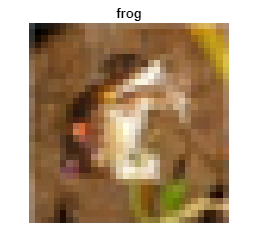

imshow(I, [])
title(label_map(label_idx))
truesize([200 200])

## Split data

Use the following splits of the ciFAIR-10/100 dataset for testing **small-data performance**

`Train` comprises the first 30 training images from each class and `val` the following 20. `trainval` is a combination of both. `test` is the full original ciFAIR-10 test set.

% 原資料的 batch data 是 10000 筆資料，現在只需要切割成小資料

respective_data = containers.Map();

% 先將不同 class 的 label 個別分離
for label_id = 1:10
    idx = find(train.labels == label_id);
    respective_data(num2str(label_id)) = train.data(idx, :);
end

respective_data.keys

ans = 1×10 cell array
    {'1'}    {'10'}    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}



% 將各 class 取指定數量加入 small data

train_small_data = zeros(300, 3072);
train_small_data_labels = categorical(label_map);
val_small_data = zeros(200, 3072);
val_small_data_labels = categorical(label_map);

% train
current_idx = 1;

for label_id = 1:10
    small_data = respective_data(num2str(label_id));
    small_data = small_data(1:30, :);
    train_small_data(current_idx:current_idx + 30 - 1, :) = small_data;
    train_small_data_labels(current_idx:current_idx + 30 - 1, 1) = label_map(label_id);
    current_idx = current_idx + 30;
end

% val
current_idx = 1;

for label_id = 1:10
    small_data = respective_data(num2str(label_id));
    small_data = small_data(31:50, :);
    val_small_data(current_idx:current_idx + 20 - 1, :) = small_data;
    val_small_data_labels(current_idx:current_idx + 20 - 1, 1) = label_map(label_id);
    current_idx = current_idx + 20;
end

train_small_data = reshape(train_small_data, [300 32 32 3]);
train_small_data = uint8(permute(train_small_data, [2, 3, 4, 1]));
train_small_data

train_small_data = 32×32×3×300 uint8 array
train_small_data(:,:,1,1) =

   202   206   210   212   215   218   221   222   222   222   223   224   224   224   224   224   223   220   219   223   227   225   222   216   202   194   187   190   206   218   219   217
   202   206   211   213   216   218   221   223   223   222   223   225   225   225   224   224   223   220   206   186   198   223   222   211   183   168   160   160   184   210   217   216
   204   207   212   215   218   220   222   225   226   225   227   228   228   228   226   225   227   182    96    60    80   180   225   211   165   134   124   120   149   194   216   217
   206   209   214   217   219   221   224   227   229   229   230   230   230   229   228   225   230   158    39    25    39   150   226   212   147    94    84    81   104   161   206   216
   208   211   215   218   221   223   226   230   233   232   231   232   232   232   229   226   230   158    47    30    30   119   218   211   135    70

train_small_data_labels

train_small_data_labels = 300×1 categorical array
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 



val_small_data = reshape(val_small_data, [200 32 32 3]);
val_small_data = uint8(permute(val_small_data, [2, 3, 4, 1]));
val_small_data

val_small_data = 32×32×3×200 uint8 array
val_small_data(:,:,1,1) =

   174   187   189   188   197   203   198   223   247   156    96   198   238   214   220   225   173   101    71   101   111    95   126   167   223   163   109   150   143    81    88   109
   172   185   186   185   192   196   195   228   248   202   171   219   238   223   223   224   180   106    72    98   115    99   118   163   226   176    98    84    56    55    90   113
   173   186   186   187   192   193   195   227   232   206   207   229   230   215   218   217   180   110    69   106   112    89   132   172   233   186    97    52     0    35    89   117
   176   185   185   189   193   194   202   193   134    88   105   195   217   206   210   203   171   124    84   107   105    82   133   173   236   200   102    75    60    54    83   115
   180   184   180   186   192   189   191   153    93    70   112   198   221   205   207   200   168   127    82    96    97    87   144   177   238   214   1

val_small_data_labels

val_small_data_labels = 200×1 categorical array
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     airplane 
     automobile 
     automobile 
     automobile 
     automobile 
     automobile 
     automobile 
     automobile 
     automobile 
     automobile 
     automobile 


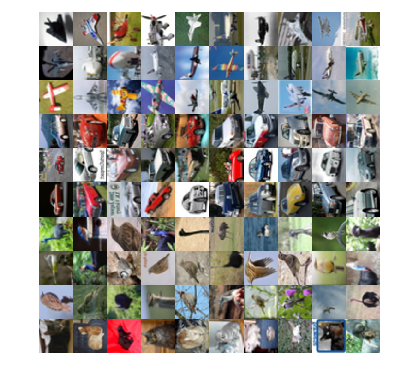


figure
thumbnails = uint8(train_small_data(:, :, :, 1:100));
montage(thumbnails)

trainDirectory = './data/cifar10/train';
valDirectory = './data/cifar10/val';

% create small data store
if ~exist(trainDirectory, 'dir') || ~exist(valDirectory, 'dir')
    mkdir(trainDirectory)
    mkdir(valDirectory)

    for i = 1:10
        mkdir(append(trainDirectory, '/', string(label_map(i))))
        mkdir(append(valDirectory, '/', string(label_map(i))))
    end
end

% save small data into created folder
for i = 1:size(train_small_data, 4)
    label = string(train_small_data_labels(i));
    image = train_small_data(:, :, :, i);
    image = imrotate(image, -90);
    thisimage = append(num2str(i), '.png');
    fulldestination = fullfile(append(trainDirectory, '/', label), thisimage);  % name file relative to that directory
    imwrite(image, fulldestination);  % save the file there directory
end

for i = 1:size(val_small_data, 4)
    label = string(val_small_data_labels(i));
    image = val_small_data(:, :, :, i);
    image = imrotate(image, -90);
    thisimage = append(num2str(i), '.png');
    fulldestination = fullfile(append(valDirectory, '/', label), thisimage);  % name file relative to that directory
    imwrite(image, fulldestination);  % save the file there directory
end


## Build model

Using **ResNet 18** and **AlexNet**

alexnet_ = alexnet;
resnet18_ = resnet18;

numClasses = numel(categories(train_small_data_labels));

layersTransfer = alexnet_.Layers(1:end-3);

alexnet_layers = [
    layersTransfer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer ];

layersTransfer = removeLayers(resnet18_.layerGraph, {'fc1000', 'prob', 'ClassificationLayer_predictions'});
resnet_layers = addLayers(layersTransfer, [fullyConnectedLayer(numClasses), softmaxLayer, classificationLayer]);
resnet_layers = connectLayers(resnet_layers, 'pool5', 'fc');

train_data = imageDatastore( ...
    './data/cifar10/train', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames' ...
    );

val_data = imageDatastore( ...
    './data/cifar10/val', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames' ...
    );

### AlexNet

alexnet_inputSize = alexnet_.Layers(1).InputSize;

augTrain = augmentedImageDatastore(alexnet_inputSize(1:2), train_data);
augValidation = augmentedImageDatastore(alexnet_inputSize(1:2), val_data);

options = trainingOptions( ...
    'adam', ...
    'MiniBatchSize', 15, ...
    'MaxEpochs', 10, ...
    'InitialLearnRate', 0.00001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augValidation, ...
    'ValidationFrequency', 3, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       13.33% |       11.00% |       3.4634 |       2.9281 |      1.0000e-05 |
|       1 |           3 |       00:00:12 |        6.67% |       12.00% |       3.3749 |       2.7656 |      1.0000e-05 |
|       1 |           6 |       00:00:19 |        6.67% |       14.00% |       3.0675 |       2.5908 |      1.0000e-05 |
|       1 |           9 |       00:00:26 |       33.33% |       17.00% |       2.8541 |   

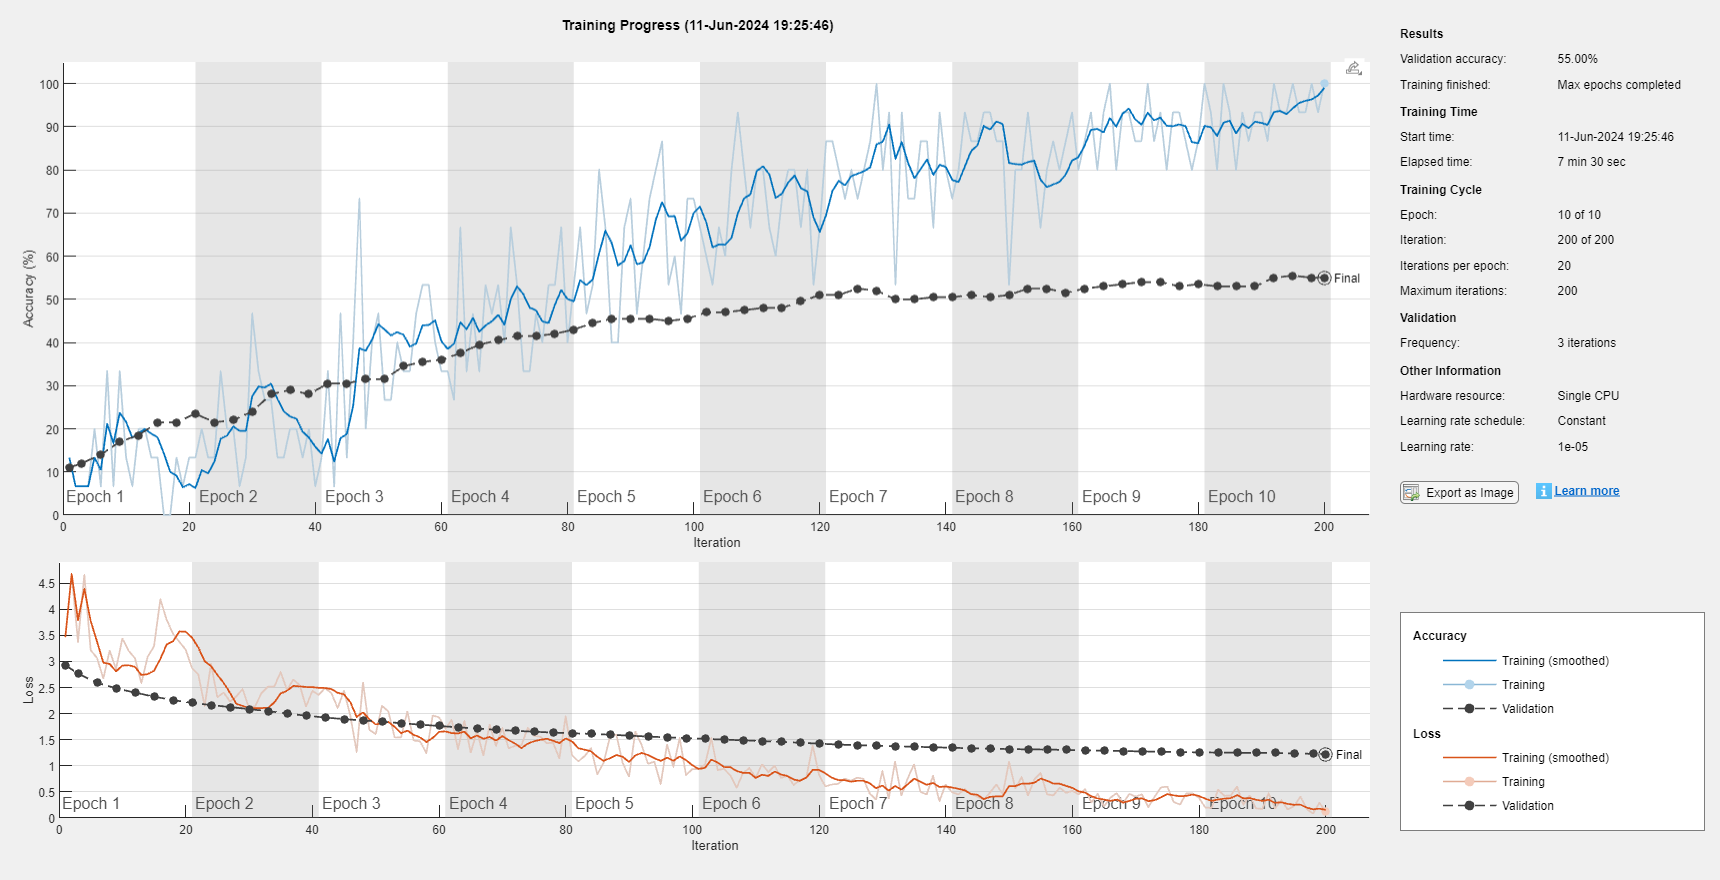

alexnet_transfer = trainNetwork(augTrain, alexnet_layers, options);

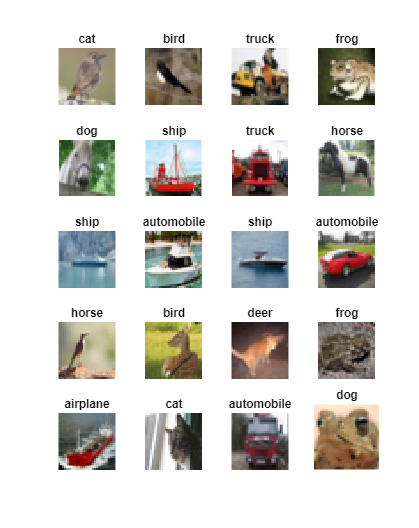

clf('reset')

[YPred, scores] = classify(alexnet_transfer, augValidation);

idx = randperm(numel(augValidation.Files), 20);

figure
for i = 1:20
    subplot(5,4,i)
    I = readimage(val_data, idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(label);
end

truesize([100 100])


YValidation = val_data.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.5500

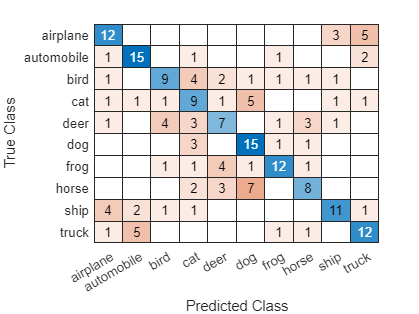


YValidation = label_map(val_data.Labels);
YPred = label_map(YPred);

figure
confusionchart(YValidation, YPred)

測試:

learning rate = 0.0001 訓練效果不錯

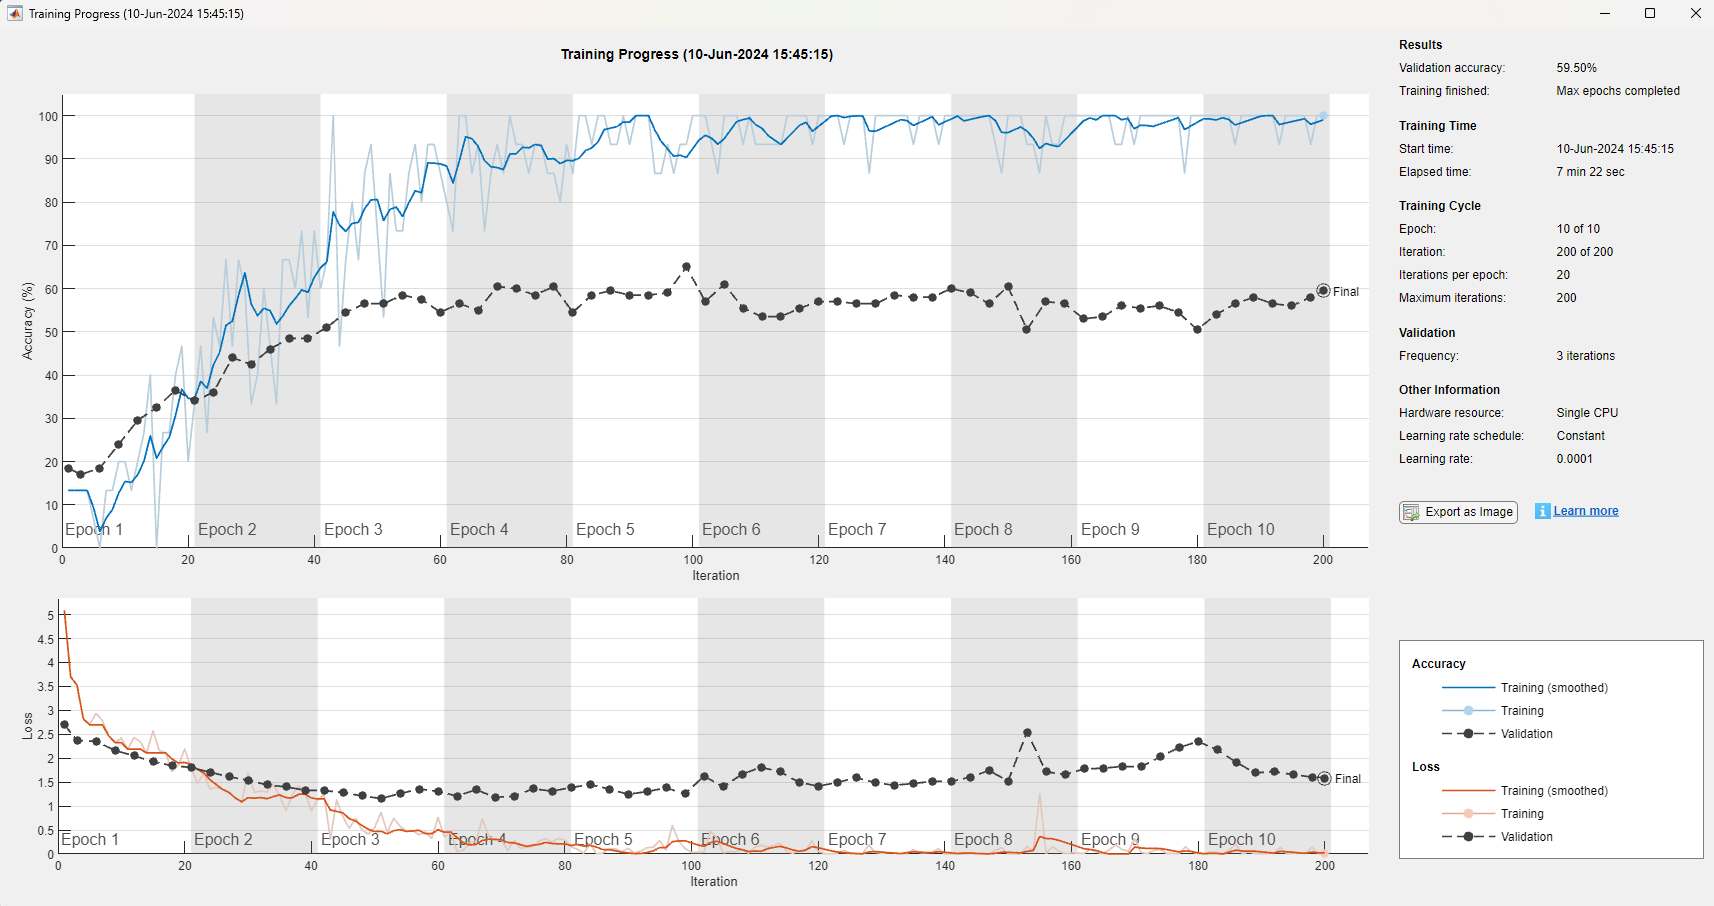

learning rate = 0.001 幾乎無法正確訓練

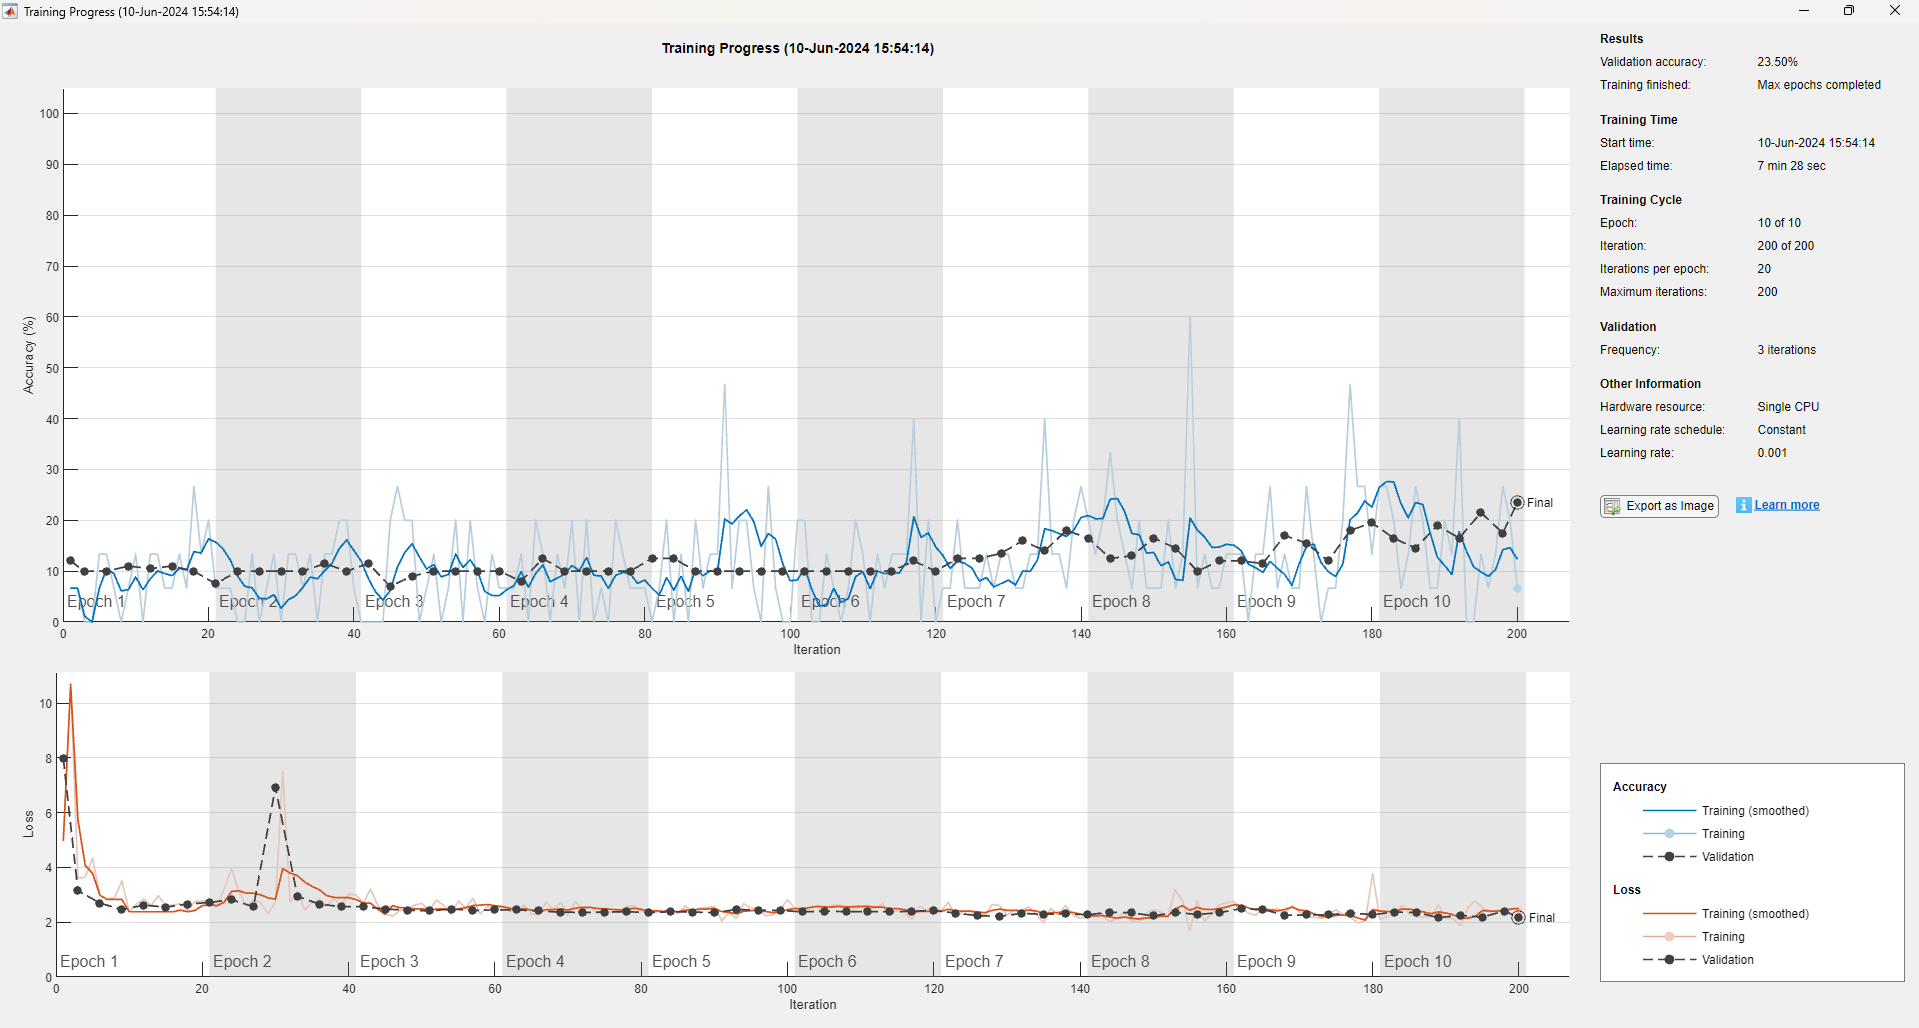

learning rate = 0.00001 效果也不錯

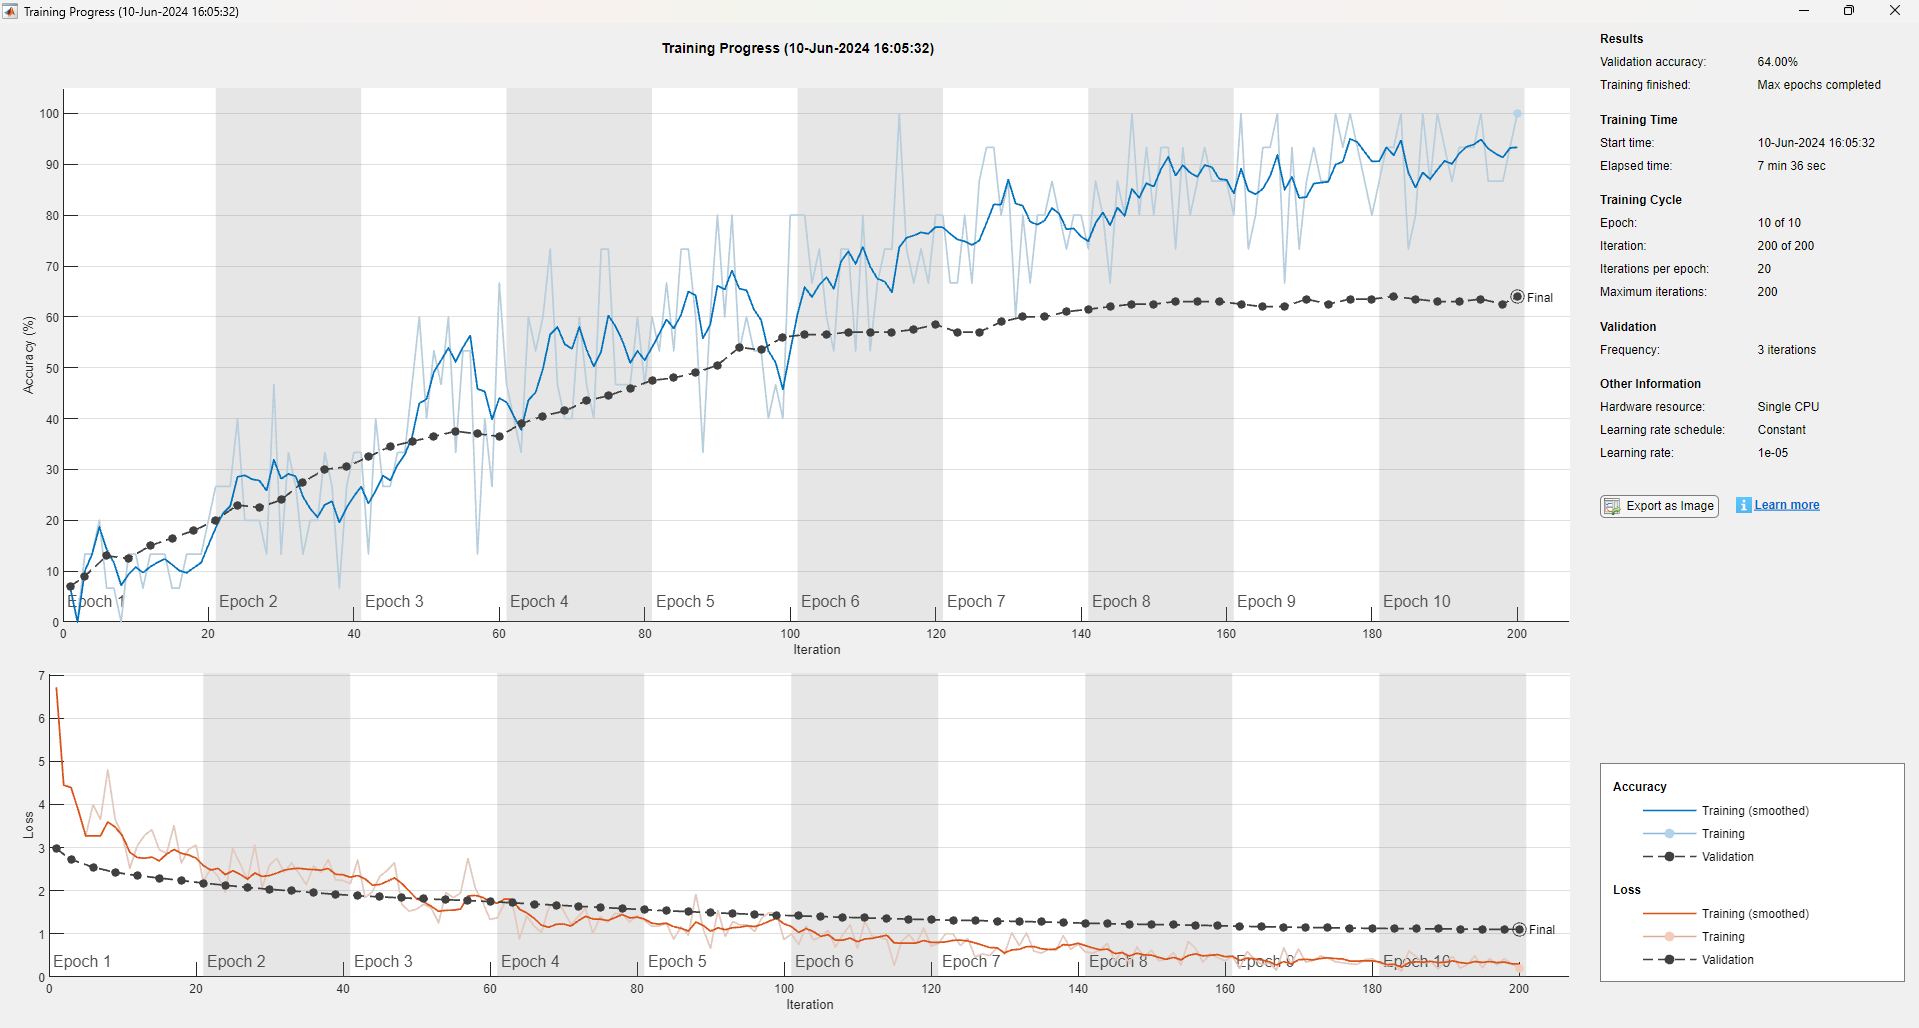

### ResNet-18

resnet_inputSize = resnet18_.Layers(1).InputSize;

augTrain = augmentedImageDatastore(resnet_inputSize(1:2), train_data);
augValidation = augmentedImageDatastore(resnet_inputSize(1:2), val_data);

options = trainingOptions( ...
    'adam', ...
    'MiniBatchSize', 15, ...
    'MaxEpochs', 10, ...
    'InitialLearnRate', 0.0001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augValidation, ...
    'ValidationFrequency', 3, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |        6.67% |       13.50% |       3.0976 |       2.9169 |      1.0000e-04 |
|       1 |           3 |       00:00:23 |        6.67% |       20.50% |       2.9201 |       2.5353 |      1.0000e-04 |
|       1 |           6 |       00:00:38 |       26.67% |       26.00% |       2.4718 |       2.2234 |      1.0000e-04 |
|       1 |           9 |       00:00:52 |       26.67% |       36.50% |       2.2555 |   

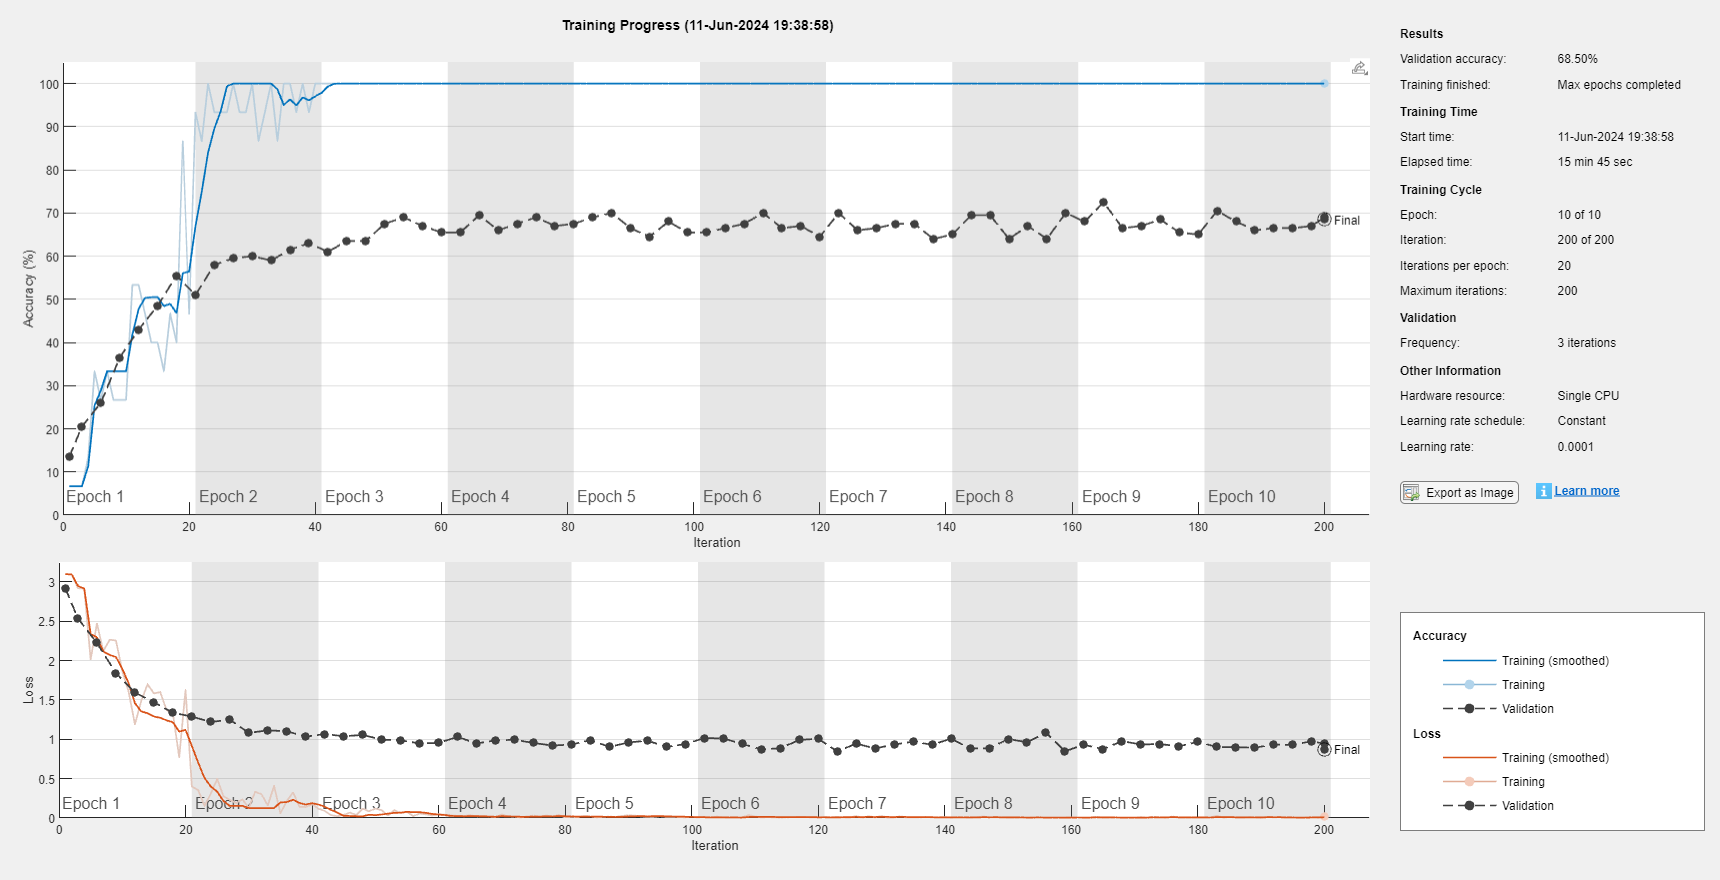

resnet_transfer = trainNetwork(augTrain, resnet_layers, options);

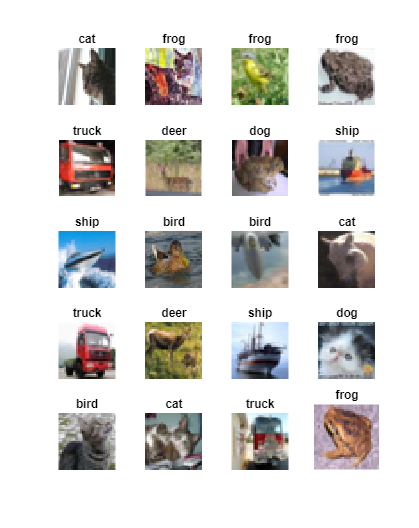

clf('reset')

[YPred, scores] = classify(resnet_transfer, augValidation);

idx = randperm(numel(augValidation.Files), 20);

figure
for i = 1:20
    subplot(5,4,i)
    I = readimage(val_data, idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(label);
end

truesize([100 100])


YValidation = val_data.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.6850

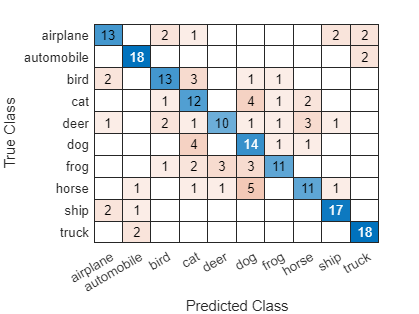


YValidation = label_map(val_data.Labels);
YPred = label_map(YPred);

figure
confusionchart(YValidation, YPred)

測試:

learning rate = 0.001 效果不好

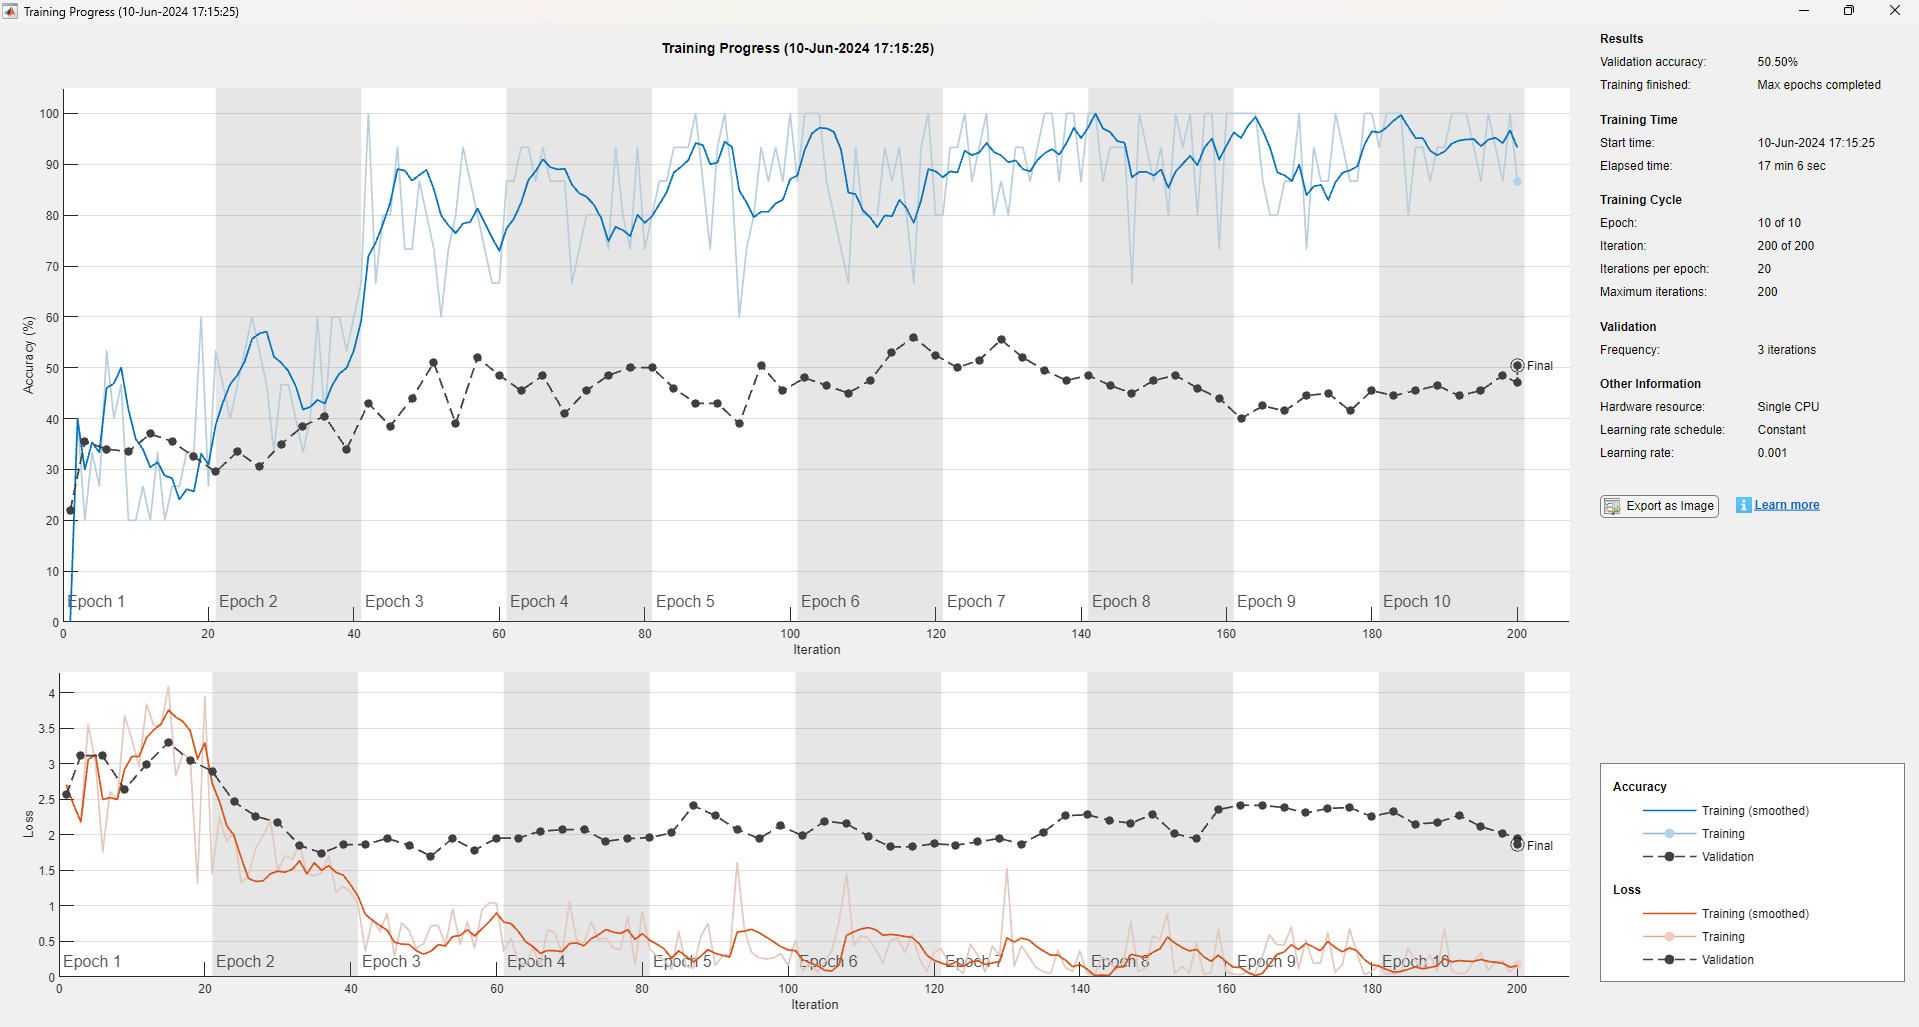

learning rate = 0.0001

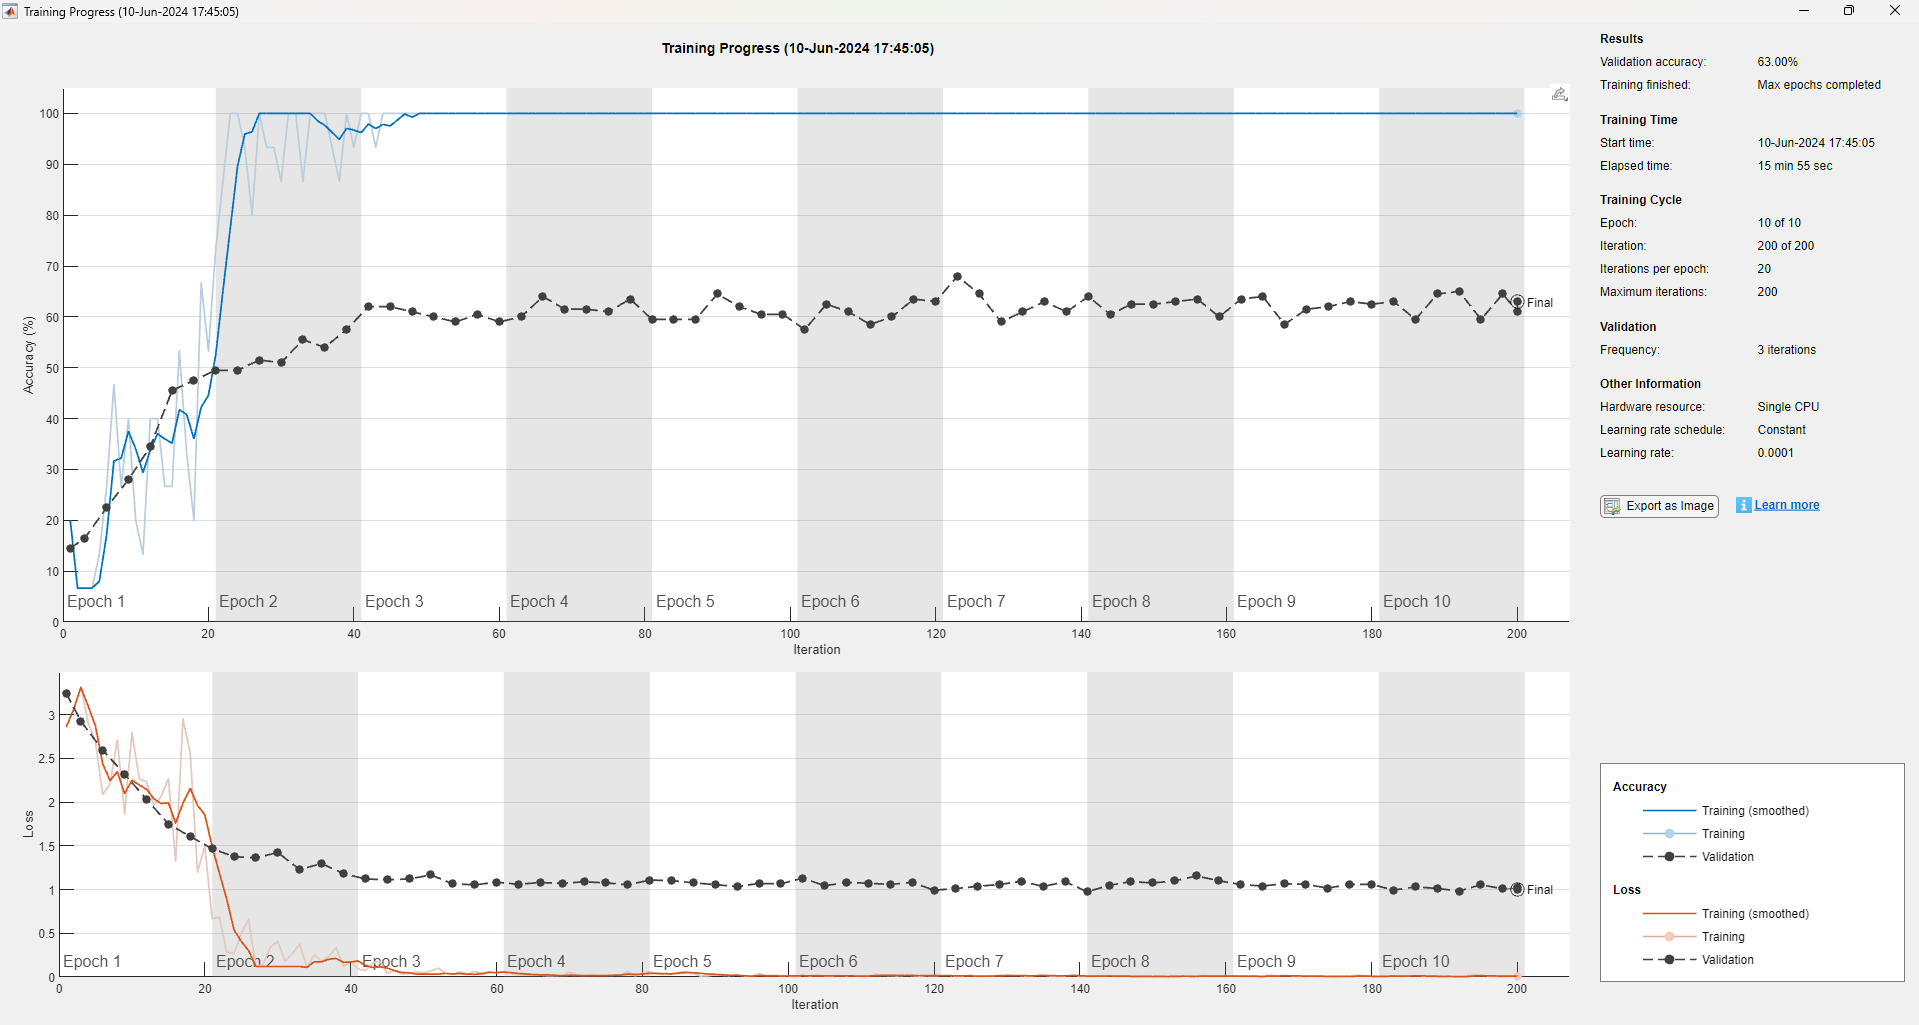

learning rate = 0.00001